# Robotics 2 20 06 5

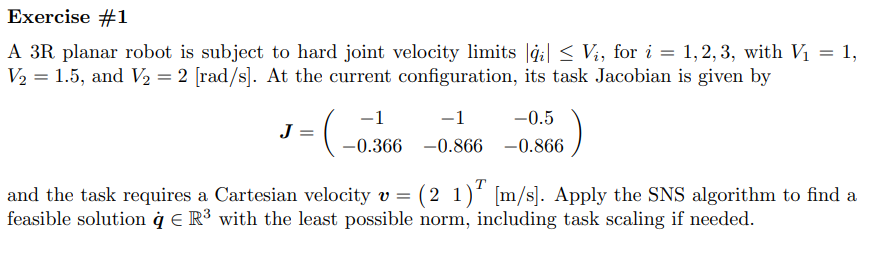

% clear all; clc;close all;
% V_=[2,1]'
% q_dMax_ = [1,1.5,2] % Maximum acceleration constraints of joints
% % 
% q_dMaxTemp_ = q_dMax_ % Maximum acceleration constraints of joints
% % V_=[0,10]'
% qnum = 3; %Number of joints
% q = sym('q', [1 qnum],'real');
% d = sym('d', [1 qnum],'real');
% a = sym('a', [1 qnum],'real');
% % 
% L = sym('l','real')
% L_=2
% % % a, alpha, 
% R3Robot = [L 0 0 q(1);
%            L 0 0 q(2);
% %            L 0 0 q(3);
%            L 0 0 q(3)]
% %        
% T0_EE = getTransformationMatrix(R3Robot)
% % 
% % % Calculate the Jacobian (Rotational)
% config = 'RRR';
% [Jp, Jo,Jps, Jos] = getJacobian(R3Robot,config)
% % %Jac = [Jp;Jo]
% % %Eliminate the zero rows, which represent the unused variables
% Jp = Jp(~all(Jp == 0,2),:)
% % 
% q_ = [pi/4,pi/4, pi/3]
% 
% % J_ = subs(Jp, [q L], [q_ L_])
% J_ =sym([-1 -1 -0.5;-0.366 -0.866 -0.866])
% % digits(5)
% % vpa(J_)
% rank_J_=rank(J_)
% rank_V_=rank(V_)
% if(rank_J_<2)
% disp("Range of J_ is lower than 2  IT IS NOT FULL RANK PAY ATTENTION!!")
% if(rank_J_==rank_V_)
% disp("but The rank is inside of rank V_ all are: "+rank_J_)
% disp("BUT CHECK IF V_ INSIDE OF THE RANGE OF R{j}, SEE THE FORM WHEN IT IS OR NOT CERO!!")
% end
% end

% 
% abs_on=true;
% autodetectsign=true
%  [qdotstarFinal] = SNSMethod1(V_,J_,q_dMax_',abs_on,autodetectsign)
% 
% [qdotstarFinal,W] = SNSMethod2(V_,J_,q_dMax_')%,Qdotmin,Qdotdmax)
% 
% vpa(qdotstarFinal)
% pd2_=vpa(J_)*qdotstarFinal
% vpa(norm(qdotstarFinal))

## 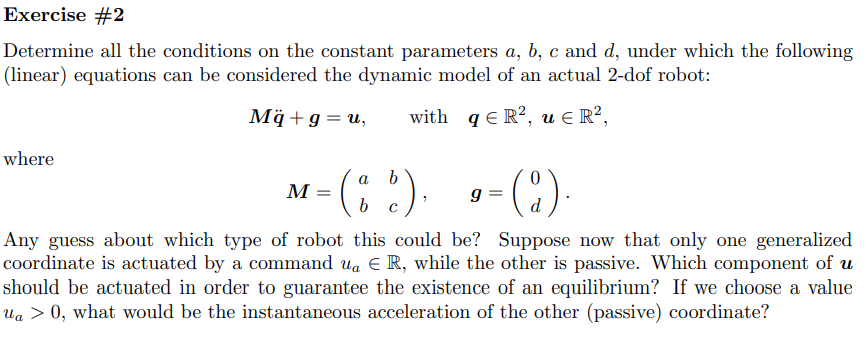

% % This part is isolated from previous section
% clear;clc
% 
% % syms k q1(t) q2(t) q3(t)
% sigma = [1,1];
% n = length(sigma);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% qd = sym('q_dot_', [n 1],'real');
% qdd = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc_', [n 1],'real');
% % k = sym('k', [n 1],'real');
% l = sym('l_', [n 1],'real');
% m = sym('m_', [n 1],'real');
% I = sym('I_', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,-g0,0]';

defining z struct

% R2Robot=['pp';'xx';sigma ]   ;    
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=qd;
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1;
% % z.dhTable=[]
% z.firstParam='alpha';
% % z.rc=[];
% % z.movingframes=[];
% z.angle_=sym(zeros(1,n));
% l_0=sym('l','real');
% % z.opt_expr={l,[l_0,l_0,l_0,l_0]'};%not necessary
% 
% % z.rcdefined=true;

## axis offset

% 
% % h=sym('h','real')
% % %x,y,z
% % z.xyx_offset=sym(zeros(3,n));
% % z.xyx_offset(:,1)=[0,h,0]';%

% %Global q reference?
% % clear
% % z.q_global
% z.global_q_reference=false;
% if(z.global_q_reference)
%     [z.q_global,z.q_dot_global]=convert_local2global_q(z.q,z.q_dot,z.sigmaD);
% end
% 

% % % R2Robot=['rr';'x~']       
% xyonly=true
% % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE(R2Robot,l,q,qd,dc,m,I,xyonly)
% % VarShortRobot.M
% z.angle_=[0,alpha_angle]
% % [Pc,vc,w,T,Ti,M] = getGenericPC(R2Robot,l,q,qd,dc,m,I,1,[],[],'alpha',false,angle_desired)
% [Pc,vc,w,T,Ti,M] = getGenericPC2(z)
% [C,cac,Csubs,S] = getCs(M,q,qd)
% 
% % [C,cac,Csubs] = getCs(Msubs,q',qd')
% u =simplify( M*qdd + cac)

% M

% isMotor=false
% [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, q, l, m, dc, g, isMotor)
% 

## linear parameterization part 1

%  [g_subs, dynamicParametersG, aG] = getDynamicParameters2(g_q,q,[],1)%l')

## part 2

% % 
%  [Yg, Ygshort] = getLinearParametrization(g_subs,aG)


## exercise 3

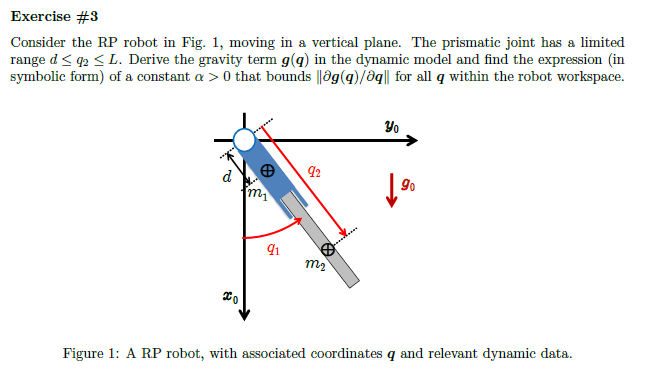

% % This part is isolated from previous section
% clear;clc;
% 
% syms k q1(t) q2(t) q3(t)
% sigma = [0,1];
% n = length(sigma);
% t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% qd = sym('q_dot_', [n 1],'real');
% qdd = sym('q_ddot_', [n 1],'real'); 
% 
% dc = sym('dc_', [n 1],'real');
% k = sym('k', [n 1],'real');
% l = sym('l_', [n 1],'real');
% m = sym('m_', [n 1],'real');
% I = sym('I_', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[g0,0,0]';

s

% R2Robot=['rp';'xx';[1,1]]    
% z = Gen_param(n);
% z.sigmaD=R2Robot
% z.l=l
% z.q=q
% z.q_dot=qd
% z.dc=dc
% z.m=m
% z.I=I
% z.methodD=1
% z.dhTable=[]
% z.firstParam='alpha'
% z.rc=[]
% z.movingframes=[]
% z.angle_=sym(zeros(1,n))
% z.opt_expr={[l(1)+q(2)],[q(2)]}
% z.rcdefined=true;

% 
%    
% xyonly=true
% % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE(R2Robot,l,q,qd,dc,m,I,xyonly)
% % VarShortRobot.M
% % angle_desired=[0,0]
% l(1)=0
% [Pc,vc,w,T,Ti,M] = getGenericPC2(z)
% [C,cac,Csubs,S] = getCs(M,q,qd)
% 
% % [C,cac,Csubs] = getCs(Msubs,q',qd')
% u =simplify( M*qdd + cac)

% isMotor=false
% [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, q, l, m, dc, g, isMotor)
% U{:}
% lambda_def=Get_A_matrix(g_q,q)
% toreplace=[cos(q(1)),sin(q(1)),q(2)]
% L=sym('L','real')
% toreplace_=[1,1,L]
% lambda1_=subs(lambda_def.lambda2_,toreplace,toreplace_)
% alpha_=sqrt(lambda1_(1))
% 


## Exercise 4

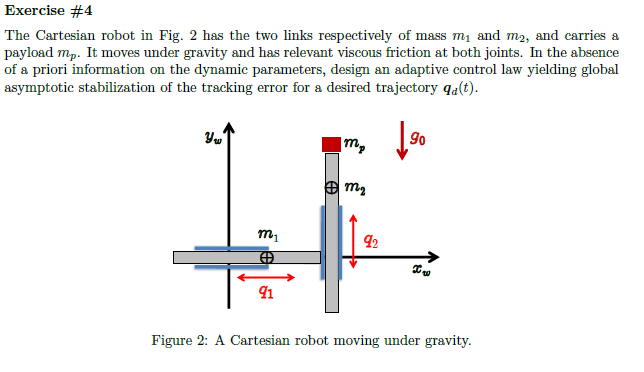

% % This part is isolated from previous section
% clear;clc
% 
% % syms k q1(t) q2(t) q3(t)
% sigma = [0,0];
% n = length(sigma);
% % t = sym('t', 'real');
% q = sym('q', [n 1],'real');
% q_d= sym('q_d', [n 1],'real');
% q_dot_d= sym('q_dot_d', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% % 
% dc = sym('dc', [n 1],'real');
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% m_p = sym('m_p','real');
% m(2)=m(2)+m_p
% I = sym('I', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,-g0,0]';

s

% R2Robot=['pp';'xy';[1,1]]    
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
% z.q_dot_d=q_dot_d;
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1
% % z.dhTable=[]
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% z.opt_expr={[l(1)+q(2)],[q(2)]};
% % z.rcdefined=true;

% 
%    
% % xyonly=true
% % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE(R2Robot,l,q,qd,dc,m,I,xyonly)
% % VarShortRobot.M
% % angle_desired=[0,0]
% % l(1)=0
% [Pc,vc,w,T,Ti,M] = getGenericPC2(z)
% [C,cac,Csubs,S] = getCs(M,q,q_dot);

Viscouz terms

% F_v=sym('F_v',[n,1],'real').*eye(n)

% isMotor=false
% [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, q, l, m, dc, g, isMotor)
% U{:}

## get dinamyc paramters

% [Msubs, dynamicParameters, aM] = getDynamicParameters(M,q,[])
% [Gsubs, dynamicParametersG, aG] = getDynamicParameters(g_q,q,[g0],2)
% [All, dynamicParamsReturn, a]= getDynamicParameters([M,diag(g_q),F_v],q,[q_dot.',g0],2)

% 
% % [C,cac,Csubs] = getCs(Msubs,q',qd';)
% u =simplify( M*q_ddot + cac+g_q+F_v*q_dot)
% [usubs, dynamicParametersu, au] = getDynamicParameters2(u,q,[])
% 
% Msubs = All(:,1:n)
% gSubs = diag(All(:,n+1:2*n))
% FSubs = All(:,2*n+1:end)

% u_subs = Msubs*q_ddot + gSubs +FSubs*q_dot

## Linearization

% Y=sym('Y','real')
% Y_=getLinearParametrization(u_subs,a)

## Adpative control law

% z_u.Y=Y;
% z_u.Y_=Y_;
% z_u.q=q;
% z_u.q_d=q_d%q desired
% z_u.q_dot_d=q_dot_d
% t=sym('t','real');
% q_dots=derivate_D(q_d,n,t,'q_d');
% z_u.q_d_dot =q_dots.dot;
% z_u.q_d_ddot=q_dots.ddot;
% z_u.a=a;
% z_u.n=n;
% z_u.q_dot=q_dot;
% z_u.q_ddot=q_ddot;
% 
% u_control=Adpatative_Control_Law(z_u)
% u_control.Y_r_
% u_control.u
% u_control.u_
% u_control.a_hat_dot
% u_control.a_hat_dot_
% u_control.mq_r_dot %I'm not sure about this
% u_control.q_r_dot_

## 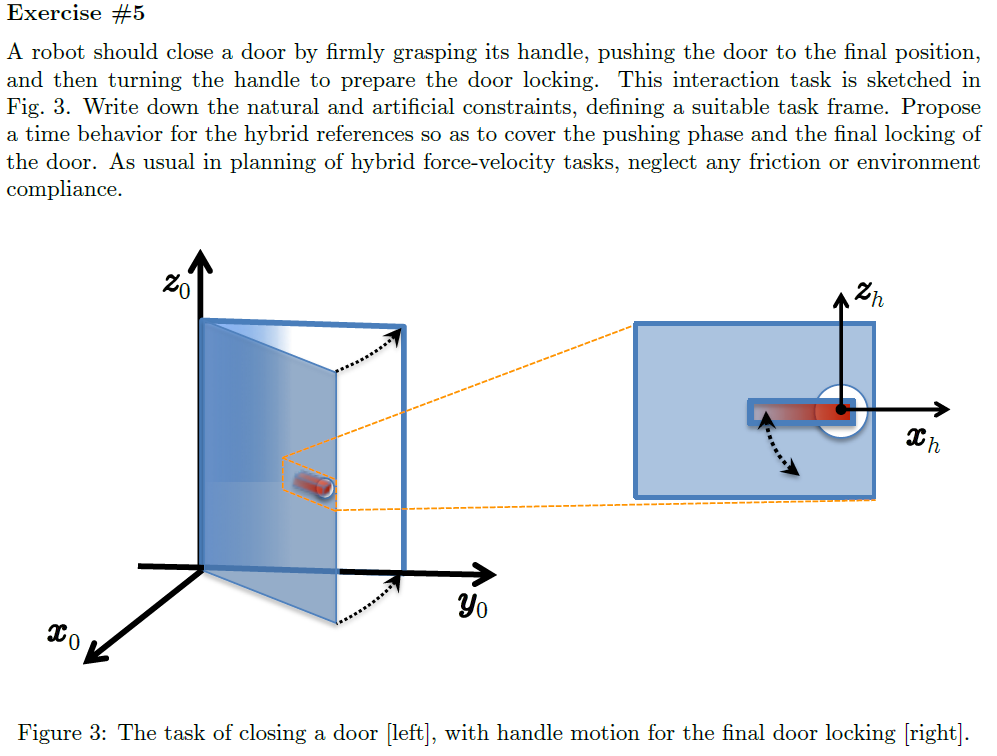

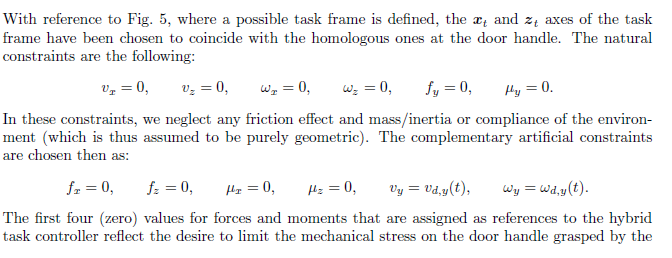

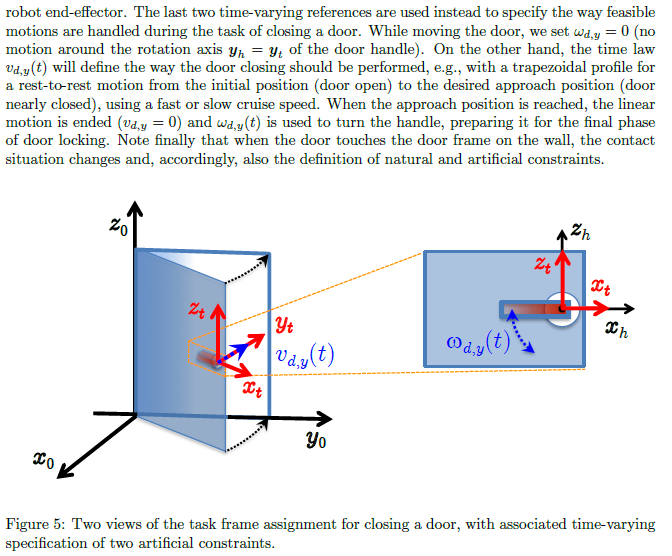

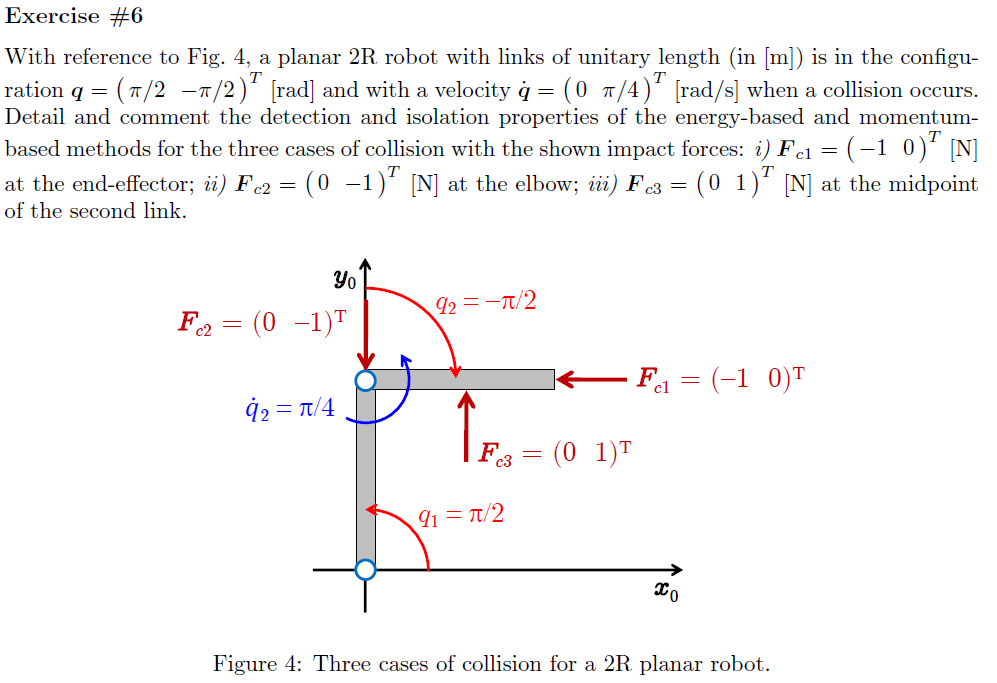

% This part is isolated from previous section
clear;clc;

% syms k q1(t) q2(t) q3(t)
sigma = [0,0];
n = length(sigma);
% t = sym('t', 'real');
q = sym('q', [n 1],'real');
q_d= sym('q_d', [n 1],'real');
q_dot = sym('q_dot_', [n 1],'real');
q_ddot = sym('q_ddot_', [n 1],'real');
% 
dc = sym('dc', [n 1],'real');
% k = sym('k', [n 1],'real');
l = sym('l', [n 1],'real');
m = sym('m', [n 1],'real');
m_p = sym('m_p','real');
m(2)=m(2)+m_p;
I = sym('I', [n 1],'real');
alpha_angle=sym('alpha','real');
g0 = sym('g0','real');
g=[0,0,-g0]';
R2Robot=['rr';'xx';sigma]    

R2Robot = 3×2 char array
    'rr'
    'xx'
    '  '


z = Gen_param(n);
z.g=g;
z.g0=g0;
z.sigmaD=R2Robot;
z.l=l;
z.q=q;
z.q_dot=q_dot;
z.dc=dc;
z.m=m;
z.I=I;
z.methodD=1;
% z.dhTable=[]
z.firstParam='alpha';
% z.rc=[]
% z.movingframes=[]
z.angle_=sym(zeros(1,n));
z.l_=[1,1]';

% z.opt_expr={[l;dc],[z.l_;z.l_/2]};
% z.rcdefined=true;

## defining collisions


% collide1=
z.collides=[struct('F',[-1,0,0]' ,'joint',2,'F_pos',l(2)),
            struct('F',[0,-1,0]' ,'joint',1,'F_pos',l(1)),
            struct('F',[0, 1,0]' ,'joint',2,'F_pos',l(2)/2)
            ];
z.collides(2)

ans = struct with fields:
        F: [3×1 double]
    joint: 1
    F_pos: [1×1 sym]


## computing


% 
%    
% % xyonly=true
% % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE(R2Robot,l,q,qd,dc,m,I,xyonly)
% % VarShortRobot.M
% % angle_desired=[0,0]
z.q_=[pi/2,-pi/2]';
z.q_dot_=[0,pi/4]';
[Pc,vc,w,T,Ti,M,VarShortRobot,Trans,zout] = getCollisions(z)

rcdefined = logical
   1


z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: [2×1 double]
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: [2×1 double]
                  q_dot_: [2×1 double]
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: []
                collides: [3×1 struct]
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset

si falla aquí está el error


$$a = l_{1}$$

d = 0

$$a = l_{2}$$

d = 0

method with PC , pay attention!
moving frames OFF!!


$$Ti = \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2}$$

moving frames OFF!!


$$Ti = \left(\begin{array}{cc} \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2} & \frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2}+\left(\frac{m_{2}}{2}+\frac{m_{p}}{2}\right)\,\left(\left({{\mathrm{dc}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,l_{1}+{l_{1}}^{2}\right)\,{{\dot{q}}_{1}}^{2}+\left(2\,{{\mathrm{dc}}_{2}}^{2}+2\,l_{1}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\right)\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}\right) \end{array}\right)$$

$$To\_derive = \left(\begin{array}{cc} -l_{2}\,\sin\left(q_{1}+q_{2}\right)-l_{1}\,\sin\left(q_{1}\right) & -l_{2}\,\sin\left(q_{1}+q_{2}\right)\\ l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right) & l_{2}\,\cos\left(q_{1}+q_{2}\right)\\ 0 & 0 \end{array}\right)$$

$$q\_t = \left(\begin{array}{c} q_{1}\left(t\right)\\ q_{2}\left(t\right) \end{array}\right)$$

    "check the _ last term it is needed for the function for example q_1_ should be the right way to define a varaible to convert to time dependent"



z_derivated = struct with fields:
    dot_t: [3×2 sym]


z_derivated = struct with fields:
     dot_t: [3×2 sym]
    ddot_t: [3×2 sym]


z_derivated = struct with fields:
     dot_t: [3×2 sym]
    ddot_t: [3×2 sym]
    tdot_t: [3×2 sym]


z_derivated = struct with fields:
        dot_t: [3×2 sym]
       ddot_t: [3×2 sym]
       tdot_t: [3×2 sym]
          dot: [3×2 sym]
    dot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
        dot_t: [3×2 sym]
       ddot_t: [3×2 sym]
       tdot_t: [3×2 sym]
          dot: [3×2 sym]
    dot_short: []


z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []


z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []
          tdot: [3×2 sym]
    tdot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []
          tdot: [3×2 sym]
    tdot_short: []


moving frames OFF!!


$$Vc\_T\_dot\_Fk = {\dot{q}}_{1}\,\left(l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\right)+l_{2}\,{\dot{q}}_{2}\,\sin\left(q_{1}+q_{2}\right)$$

$$Tau\_c = \left(\begin{array}{c} l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\\ l_{2}\,\sin\left(q_{1}+q_{2}\right) \end{array}\right)$$

zout = struct with fields:
    J_c_collisions_: {[3×2 sym]}


moving frames OFF!!


$$Vc\_T\_dot\_Fk = \left(\begin{array}{c} {\dot{q}}_{1}\,\left(l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\right)+l_{2}\,{\dot{q}}_{2}\,\sin\left(q_{1}+q_{2}\right)\\ -l_{1}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right) \end{array}\right)$$

$$Tau\_c = \left(\begin{array}{cc} l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right) & -l_{1}\,\cos\left(q_{1}\right)\\ l_{2}\,\sin\left(q_{1}+q_{2}\right) & 0 \end{array}\right)$$

zout = struct with fields:
    J_c_collisions_: {[3×2 sym]  [3×2 sym]}


moving frames OFF!!


$$Vc\_T\_dot\_Fk = \left(\begin{array}{c} {\dot{q}}_{1}\,\left(l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\right)+l_{2}\,{\dot{q}}_{2}\,\sin\left(q_{1}+q_{2}\right)\\ -l_{1}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right)\\ {\dot{q}}_{1}\,\left(\frac{l_{2}\,\cos\left(q_{1}+q_{2}\right)}{2}+l_{1}\,\cos\left(q_{1}\right)\right)+\frac{l_{2}\,{\dot{q}}_{2}\,\cos\left(q_{1}+q_{2}\right)}{2} \end{array}\right)$$

$$Tau\_c = \left(\begin{array}{ccc} l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right) & -l_{1}\,\cos\left(q_{1}\right) & \frac{l_{2}\,\cos\left(q_{1}+q_{2}\right)}{2}+l_{1}\,\cos\left(q_{1}\right)\\ l_{2}\,\sin\left(q_{1}+q_{2}\right) & 0 & \frac{l_{2}\,\cos\left(q_{1}+q_{2}\right)}{2} \end{array}\right)$$

zout = struct with fields:
    J_c_collisions_: {[3×2 sym]  [3×2 sym]  [3×2 sym]}


>> Getting  the Christoffel’sym. Might take a while...
*** Computation of Potential Energy (Jacobian-based method) 


$$qall\_sincos\_comb = \left(\begin{array}{cccccc} \sin\left(q_{1}\right) & \sin\left(q_{2}\right) & \sin\left(q_{1}+q_{2}\right) & \cos\left(q_{1}\right) & \cos\left(q_{2}\right) & \cos\left(q_{1}+q_{2}\right) \end{array}\right)$$

$$PE = 0$$

$$PE\_short = 0$$

$$g\_q\_short = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

zout = struct with fields:
    J_c_collisions_: {[3×2 sym]  [3×2 sym]  [3×2 sym]}
                  C: {[2×2 sym]  [2×2 sym]}
                cac: [2×1 sym]
              Csubs: {[2×2 sym]  [2×2 sym]}
                  S: [2×2 sym]
                g_q: [2×1 sym]
                 PE: [1×1 sym]
                  U: {[1×1 sym]  [1×1 sym]}
          g_q_short: [2×1 sym]
           PE_short: [1×1 sym]


zout = struct with fields:
    J_c_collisions_: {[3×2 sym]  [3×2 sym]  [3×2 sym]}
                  C: {[2×2 sym]  [2×2 sym]}
                cac: [2×1 sym]
              Csubs: {[2×2 sym]  [2×2 sym]}
                  S: [2×2 sym]
                g_q: [2×1 sym]
                 PE: [1×1 sym]
                  U: {[1×1 sym]  [1×1 sym]}
          g_q_short: [2×1 sym]
           PE_short: [1×1 sym]


zout = struct with fields:
    J_c_collisions_: {[3×2 sym]  [3×2 sym]  [3×2 sym]}
                  C: {[2×2 sym]  [2×2 sym]}
                cac: [2×1 sym]
              Csubs: {[2×2 sym]  [2×2 sym]}
                  S: [2×2 sym]
                g_q: [2×1 sym]
                 PE: [1×1 sym]
                  U: {[1×1 sym]  [1×1 sym]}
          g_q_short: [2×1 sym]
           PE_short: [1×1 sym]


zout = struct with fields:
    J_c_collisions_: {[3×2 sym]  [3×2 sym]  [3×2 sym]}
                  C: {[2×2 sym]  [2×2 sym]}
                cac: [2×1 sym]
              Csubs: {[2×2 sym]  [2×2 sym]}
                  S: [2×2 sym]
                g_q: [2×1 sym]
                 PE: [1×1 sym]
                  U: {[1×1 sym]  [1×1 sym]}
          g_q_short: [2×1 sym]
           PE_short: [1×1 sym]


zout = struct with fields:
    J_c_collisions_: {[3×2 sym]  [3×2 sym]  [3×2 sym]}
                  C: {[2×2 sym]  [2×2 sym]}
                cac: [2×1 sym]
              Csubs: {[2×2 sym]  [2×2 sym]}
                  S: [2×2 sym]
                g_q: [2×1 sym]
                 PE: [1×1 sym]
                  U: {[1×1 sym]  [1×1 sym]}
          g_q_short: [2×1 sym]
           PE_short: [1×1 sym]


$$Pc = \left(\begin{array}{cc} {\mathrm{dc}}_{1}\,\cos\left(q_{1}\right) & {\mathrm{dc}}_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\\ {\mathrm{dc}}_{1}\,\sin\left(q_{1}\right) & {\mathrm{dc}}_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\\ 0 & 0 \end{array}\right)$$

$$vc = \left(\begin{array}{cc} -{\mathrm{dc}}_{1}\,{\dot{q}}_{1}\,\sin\left(q_{1}\right) & -{\dot{q}}_{1}\,\left({\mathrm{dc}}_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\right)-{\mathrm{dc}}_{2}\,{\dot{q}}_{2}\,\sin\left(q_{1}+q_{2}\right)\\ {\mathrm{dc}}_{1}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right) & {\dot{q}}_{1}\,\left({\mathrm{dc}}_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\right)+{\mathrm{dc}}_{2}\,{\dot{q}}_{2}\,\cos\left(q_{1}+q_{2}\right)\\ 0 & 0 \end{array}\right)$$

$$w = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ {\dot{q}}_{1} & {\dot{q}}_{1}+{\dot{q}}_{2} \end{array}\right)$$

$$T = \frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2}+\frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2}+\left(\frac{m_{2}}{2}+\frac{m_{p}}{2}\right)\,\left(\left({{\mathrm{dc}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,l_{1}+{l_{1}}^{2}\right)\,{{\dot{q}}_{1}}^{2}+\left(2\,{{\mathrm{dc}}_{2}}^{2}+2\,l_{1}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\right)\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}\right)$$

$$Ti = \left(\begin{array}{cc} \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2} & \frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2}+\left(\frac{m_{2}}{2}+\frac{m_{p}}{2}\right)\,\left(\left({{\mathrm{dc}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,l_{1}+{l_{1}}^{2}\right)\,{{\dot{q}}_{1}}^{2}+\left(2\,{{\mathrm{dc}}_{2}}^{2}+2\,l_{1}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\right)\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}\right) \end{array}\right)$$

$$M = \begin{array}{l} \left(\begin{array}{cc} I_{1}+I_{2}+{{\mathrm{dc}}_{1}}^{2}\,m_{1}+{{\mathrm{dc}}_{2}}^{2}\,m_{2}+{{\mathrm{dc}}_{2}}^{2}\,m_{p}+{l_{1}}^{2}\,m_{2}+{l_{1}}^{2}\,m_{p}+2\,{\mathrm{dc}}_{2}\,l_{1}\,m_{2}\,\cos\left(q_{2}\right)+2\,{\mathrm{dc}}_{2}\,l_{1}\,m_{p}\,\cos\left(q_{2}\right) & \sigma_{1}\\ \sigma_{1} & I_{2}+{{\mathrm{dc}}_{2}}^{2}\,m_{2}+{{\mathrm{dc}}_{2}}^{2}\,m_{p} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=I_{2}+{{\mathrm{dc}}_{2}}^{2}\,m_{2}+{{\mathrm{dc}}_{2}}^{2}\,m_{p}+{\mathrm{dc}}_{2}\,l_{1}\,m_{2}\,\cos\left(q_{2}\right)+{\mathrm{dc}}_{2}\,l_{1}\,m_{p}\,\cos\left(q_{2}\right) \end{array}$$

VarShortRobot = struct with fields:
    Pc: [3×2 sym]
    vc: [3×2 sym]
     w: [3×2 sym]
     T: [1×1 sym]
    Ti: [1×2 sym]
     M: [2×2 sym]


Trans = struct with fields:
                 TTotal: [4×4 sym]
                PTotali: [3×2 sym]
               TPartial: {[4×4 sym]  [4×4 sym]}
                 RTotal: [3×3 sym]
               RPartial: {[3×3 sym]  [3×3 sym]}
                 PTotal: [3×1 sym]
        Jacobian_PTotal: [3×2 sym]
    Jacobian_dot_PTotal: [3×2 sym]
               PPartial: {[3×1 sym]  [3×1 sym]}
                     Pc: [3×2 sym]
                RTotali: {[3×3 sym]  [3×3 sym]}
           ThetaPartial: [2×1 sym]
             ThetaTotal: [1×1 sym]
                     vc: [3×2 sym]
                      w: [3×2 sym]
                      T: [1×1 sym]
                     Ti: [1×2 sym]
                      M: [2×2 sym]


zout = struct with fields:
    J_c_collisions_: {[3×2 sym]  [3×2 sym]  [3×2 sym]}
                  C: {[2×2 sym]  [2×2 sym]}
                cac: [2×1 sym]
              Csubs: {[2×2 sym]  [2×2 sym]}
                  S: [2×2 sym]
                g_q: [2×1 sym]
                 PE: [1×1 sym]
                  U: {[1×1 sym]  [1×1 sym]}
          g_q_short: [2×1 sym]
           PE_short: [1×1 sym]
      Pc_collisions: [3×3 sym]
      vc_collisions: [3×3 sym]
     J_c_collisions: {[3×2 sym]  [3×2 sym]  [3×2 sym]}
        Vc_T_dot_Fk: [3×1 sym]
              Tau_c: [2×3 sym]
                p_r: [2×1 sym]
                tau: [2×1 sym]
                  r: [2×1 sym]
                P_0: [2×1 sym]
       to_integrate: [2×1 sym]
     Pc_collisions_: [3×3 sym]
     vc_collisions_: [3×3 sym]
       Vc_T_dot_Fk_: [3×1 sym]
             Tau_c_: [2×3 sym]


zout.J_c_collisions{:}

$$ans = \left(\begin{array}{cc} -l_{2}\,\sin\left(q_{1}+q_{2}\right)-l_{1}\,\sin\left(q_{1}\right) & -l_{2}\,\sin\left(q_{1}+q_{2}\right)\\ l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right) & l_{2}\,\cos\left(q_{1}+q_{2}\right)\\ 0 & 0 \end{array}\right)$$

$$ans = \left(\begin{array}{cc} -l_{1}\,\sin\left(q_{1}\right) & 0\\ l_{1}\,\cos\left(q_{1}\right) & 0\\ 0 & 0 \end{array}\right)$$

$$ans = \left(\begin{array}{cc} -\frac{l_{2}\,\sin\left(q_{1}+q_{2}\right)}{2}-l_{1}\,\sin\left(q_{1}\right) & -\frac{l_{2}\,\sin\left(q_{1}+q_{2}\right)}{2}\\ \frac{l_{2}\,\cos\left(q_{1}+q_{2}\right)}{2}+l_{1}\,\cos\left(q_{1}\right) & \frac{l_{2}\,\cos\left(q_{1}+q_{2}\right)}{2}\\ 0 & 0 \end{array}\right)$$

zout.vc_collisions

$$ans = \begin{array}{l} \left(\begin{array}{ccc} -{\dot{q}}_{1}\,\left(\sigma_{3}+l_{1}\,\sin\left(q_{1}\right)\right)-\sigma_{1} & -l_{1}\,{\dot{q}}_{1}\,\sin\left(q_{1}\right) & -{\dot{q}}_{1}\,\left(\frac{\sigma_{3}}{2}+l_{1}\,\sin\left(q_{1}\right)\right)-\frac{\sigma_{1}}{2}\\ {\dot{q}}_{1}\,\left(\sigma_{4}+l_{1}\,\cos\left(q_{1}\right)\right)+\sigma_{2} & l_{1}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right) & {\dot{q}}_{1}\,\left(\frac{\sigma_{4}}{2}+l_{1}\,\cos\left(q_{1}\right)\right)+\frac{\sigma_{2}}{2}\\ 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{2}\,{\dot{q}}_{2}\,\sin\left(q_{1}+q_{2}\right)\\ \sigma_{2}=l_{2}\,{\dot{q}}_{2}\,\cos\left(q_{1}+q_{2}\right)\\ \sigma_{3}=l_{2}\,\sin\left(q_{1}+q_{2}\right)\\ \sigma_{4}=l_{2}\,\cos\left(q_{1}+q_{2}\right) \end{array}$$

zout.Vc_T_dot_Fk

$$ans = \left(\begin{array}{c} {\dot{q}}_{1}\,\left(l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\right)+l_{2}\,{\dot{q}}_{2}\,\sin\left(q_{1}+q_{2}\right)\\ -l_{1}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right)\\ {\dot{q}}_{1}\,\left(\frac{l_{2}\,\cos\left(q_{1}+q_{2}\right)}{2}+l_{1}\,\cos\left(q_{1}\right)\right)+\frac{l_{2}\,{\dot{q}}_{2}\,\cos\left(q_{1}+q_{2}\right)}{2} \end{array}\right)$$

zout.Tau_c

$$ans = \left(\begin{array}{ccc} l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right) & -l_{1}\,\cos\left(q_{1}\right) & \frac{l_{2}\,\cos\left(q_{1}+q_{2}\right)}{2}+l_{1}\,\cos\left(q_{1}\right)\\ l_{2}\,\sin\left(q_{1}+q_{2}\right) & 0 & \frac{l_{2}\,\cos\left(q_{1}+q_{2}\right)}{2} \end{array}\right)$$


zout.J_c_collisions_{:}

$$ans = \left(\begin{array}{cc} -1 & 0\\ 1 & 1\\ 0 & 0 \end{array}\right)$$

$$ans = \left(\begin{array}{cc} -1 & 0\\ 0 & 0\\ 0 & 0 \end{array}\right)$$

$$ans = \left(\begin{array}{cc} -1 & 0\\ \frac{1}{2} & \frac{1}{2}\\ 0 & 0 \end{array}\right)$$

zout.vc_collisions_

$$ans = \left(\begin{array}{ccc} 0 & 0 & 0\\ \frac{\pi }{4} & 0 & \frac{\pi }{8}\\ 0 & 0 & 0 \end{array}\right)$$

zout.Vc_T_dot_Fk_

$$ans = \left(\begin{array}{c} 0\\ 0\\ \frac{\pi }{8} \end{array}\right)$$

zout.Tau_c_

$$ans = \left(\begin{array}{ccc} 1 & 0 & \frac{1}{2}\\ 0 & 0 & \frac{1}{2} \end{array}\right)$$


(z.q_dot_'*zout.Tau_c_)'

$$ans = \left(\begin{array}{c} 0\\ 0\\ \frac{\pi }{8} \end{array}\right)$$


vc_=subs(vc,q,z.q_)

$$vc\_ = \left(\begin{array}{cc} -{\mathrm{dc}}_{1}\,{\dot{q}}_{1} & -l_{1}\,{\dot{q}}_{1}\\ 0 & {\mathrm{dc}}_{2}\,{\dot{q}}_{1}+{\mathrm{dc}}_{2}\,{\dot{q}}_{2}\\ 0 & 0 \end{array}\right)$$

[C,cac,Csubs,S] = getCs(M,q,q_dot);

>> Getting  the Christoffel’sym. Might take a while...
